# Teoria 9/3/2020

## Crane

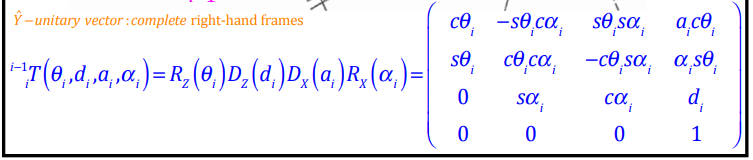

q = [0 pi];
d = [0.5, 1, 1];
a = [0 0 0];
alpha = [-pi/2, pi/2, 0];

T_1_0 = trotz(q(1))*...
      transl(0,0,d(1))*...
      trotx(alpha(1));
T_2_1 = trotz(q(2))*...
        transl(0,0,d(2))*...
        trotx(alpha(2));
T_3_2 = transl(0,0,d(3));

T_3 = T_1_0 * T_2_1 * T_3_2

T_3 =    -1.0000         0         0         0
         0    1.0000         0    1.0000
         0         0   -1.0000   -0.5000
         0         0         0    1.0000


## IRB 140

a = [0.07 0.36 0 0 0 0];
alpha = [-pi/2 0 pi/2 -pi/2 pi/2 pi/2];
d = [0.352 0 0 0.38 0 0.065];
theta = [0 0 0 0 0 0];

T = FK(alpha, a , d, theta);

T =     1.0000         0         0    0.4300
         0         0   -1.0000         0
         0    1.0000         0    0.7970
         0         0         0    1.0000



mdl_irb140
irb140.fkine(theta)

 

ans = 
         1         0         0      0.43
         0         0        -1         0
         0         1         0     0.797
         0         0         0         1


## Mistubishi

d = [1 0 0];
a = [0 2 3];
alpha = [pi/2 0 0]

alpha =     1.5708         0         0


theta = [0 0 0];

T = FK(alpha, a, d, theta)

T =      1     0     0     5
     0     0    -1     0
     0     1     0     1
     0     0     0     1


T =      1     0     0     5
     0     0    -1     0
     0     1     0     1
     0     0     0     1



mdl_3link3d
R3.fkine(theta)

 

ans = 
         1         0         0         5
         0         0        -1         0
         0         1         0         1
         0         0         0         1


function T = FK(alpha, a, d, theta)
    n = size(alpha,2);
    T = eye(4);
    for i = 1:n
        Ti = trotz(theta(i)) * transl(0,0,d(i)) * transl(a(i),0,0) * trotx(alpha(i));
        T = T * Ti;
    end
    T
end